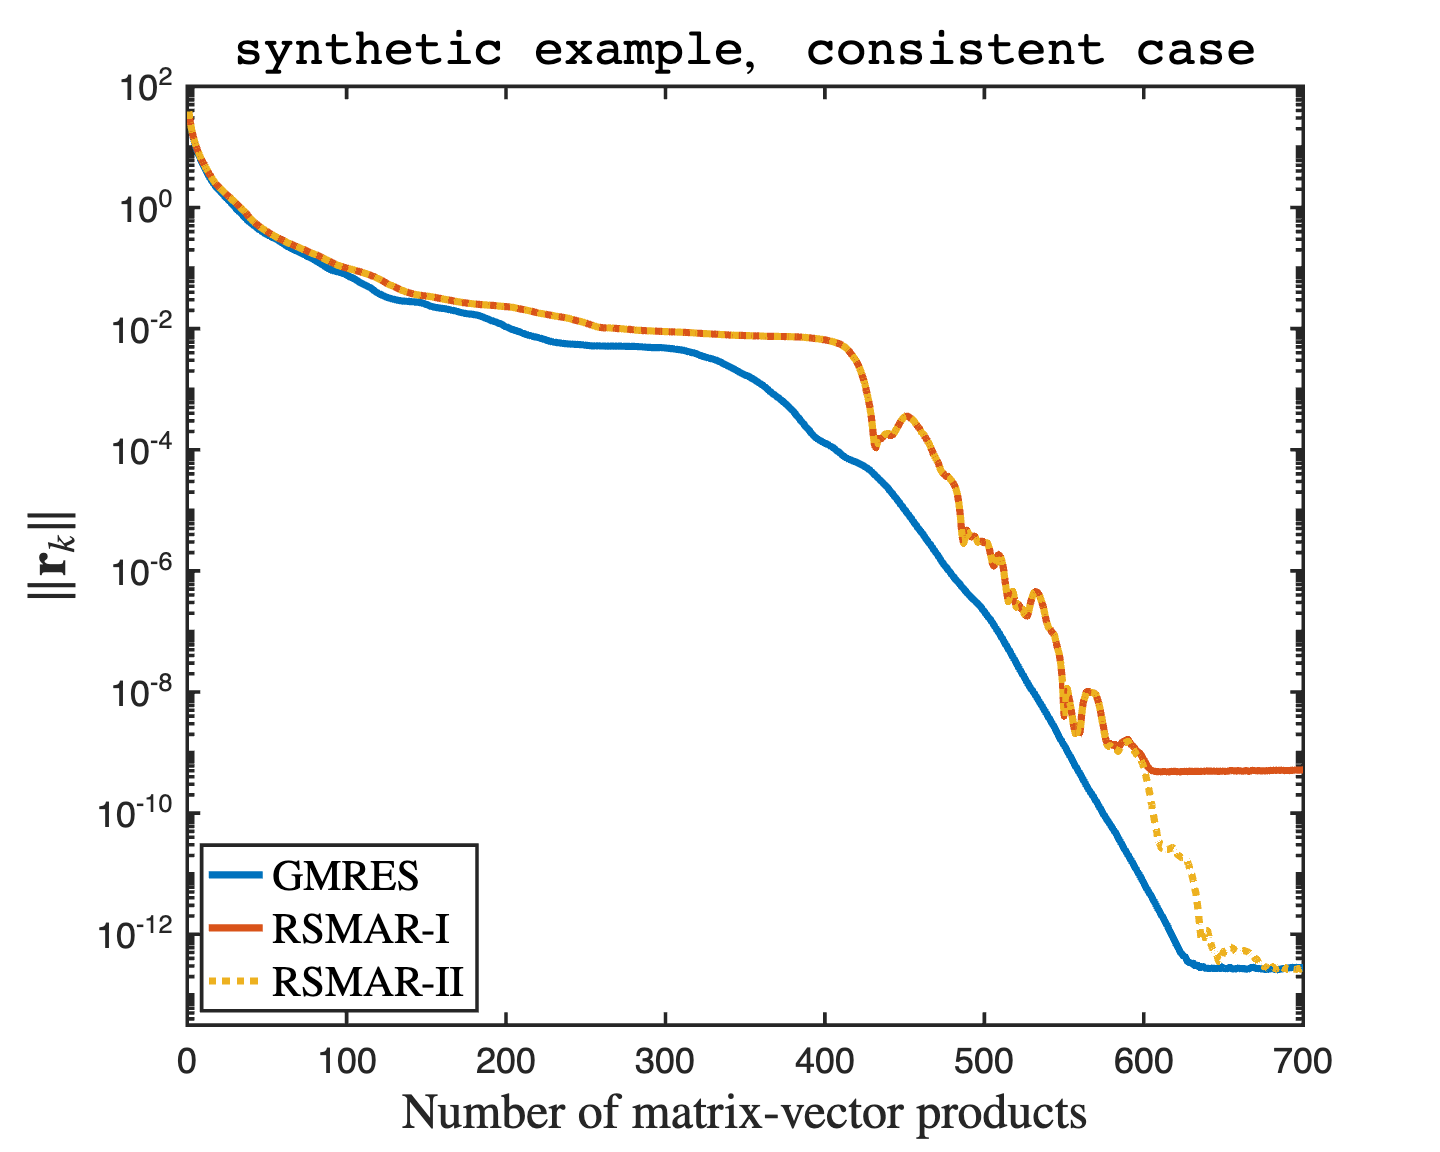

% Kui Du, Jia-Jun Fan, and Fang Wang 2025.06.16
clc; close all; clearvars;
% range symmetric singular consistent system
n = 5000; m = 3000;
rng("default"); U = orth(randn(n));
C = eye(m)+ randn(m)/sqrt(m);
A = U*[C zeros(m,n-m); zeros(n-m,m) zeros(n-m)]*U';
b = A*randn(n,1);
tol = 1e-13; maxit = 700;

[~, ~, mgs_gmres_resvec, ~] = mgs_gmres(A, b, tol, maxit);
% [~, ~, hh_gmres_resvec, ~] = hh_gmres(A, b, tol, maxit);
[~, ~, rsmar1_resvec, ~] = rsmar(A, b, tol, maxit, version=1);
[~, ~, rsmar2_resvec, ~] = rsmar(A, b, tol, maxit, version=2);
% [~, ~, lsqr_resvec, ~] = lsqr(A, b, tol, maxit);
% [~, ~, lsmr_resvec, ~] = lsmr(A, b, tol, maxit);

set(0, 'defaultaxeslinewidth',  2);
set(0, 'defaultaxesfontsize',   20);
figure('Position',[180 120 800 640]);
semilogy(1:length(mgs_gmres_resvec), mgs_gmres_resvec, LineWidth=4);
hold on;
% semilogy(1:length(hh_gmres_resvec), hh_gmres_resvec, LineWidth=4, LineStyle=":");
semilogy(1:length(rsmar1_resvec), rsmar1_resvec, LineWidth=4);
semilogy(1:length(rsmar2_resvec), rsmar2_resvec, LineWidth=4, LineStyle=":");
% semilogy(3:2:2*length(lsqr_resvec)+1, lsqr_resvec, LineWidth=4);
% semilogy(3:2:2*length(lsmr_resvec)+1, lsmr_resvec, LineWidth=4,LineStyle=":");
hold off;
xlim([0, maxit]), ylim([tol*10^(-0.5) 10^2])
title('{\tt synthetic example},\quad{\tt consistent case}', Interpreter='latex',FontSize=28);
xlabel('Number of matrix-vector products', Interpreter='latex', FontSize=28);
ylabel('$\|\mathbf{r}_k\|$', Interpreter='latex', FontSize=30);
legend({'GMRES', 'RSMAR-I', 'RSMAR-II'}, Interpreter='latex', FontSize=24, Location='SW');
print('syn_con','-depsc')

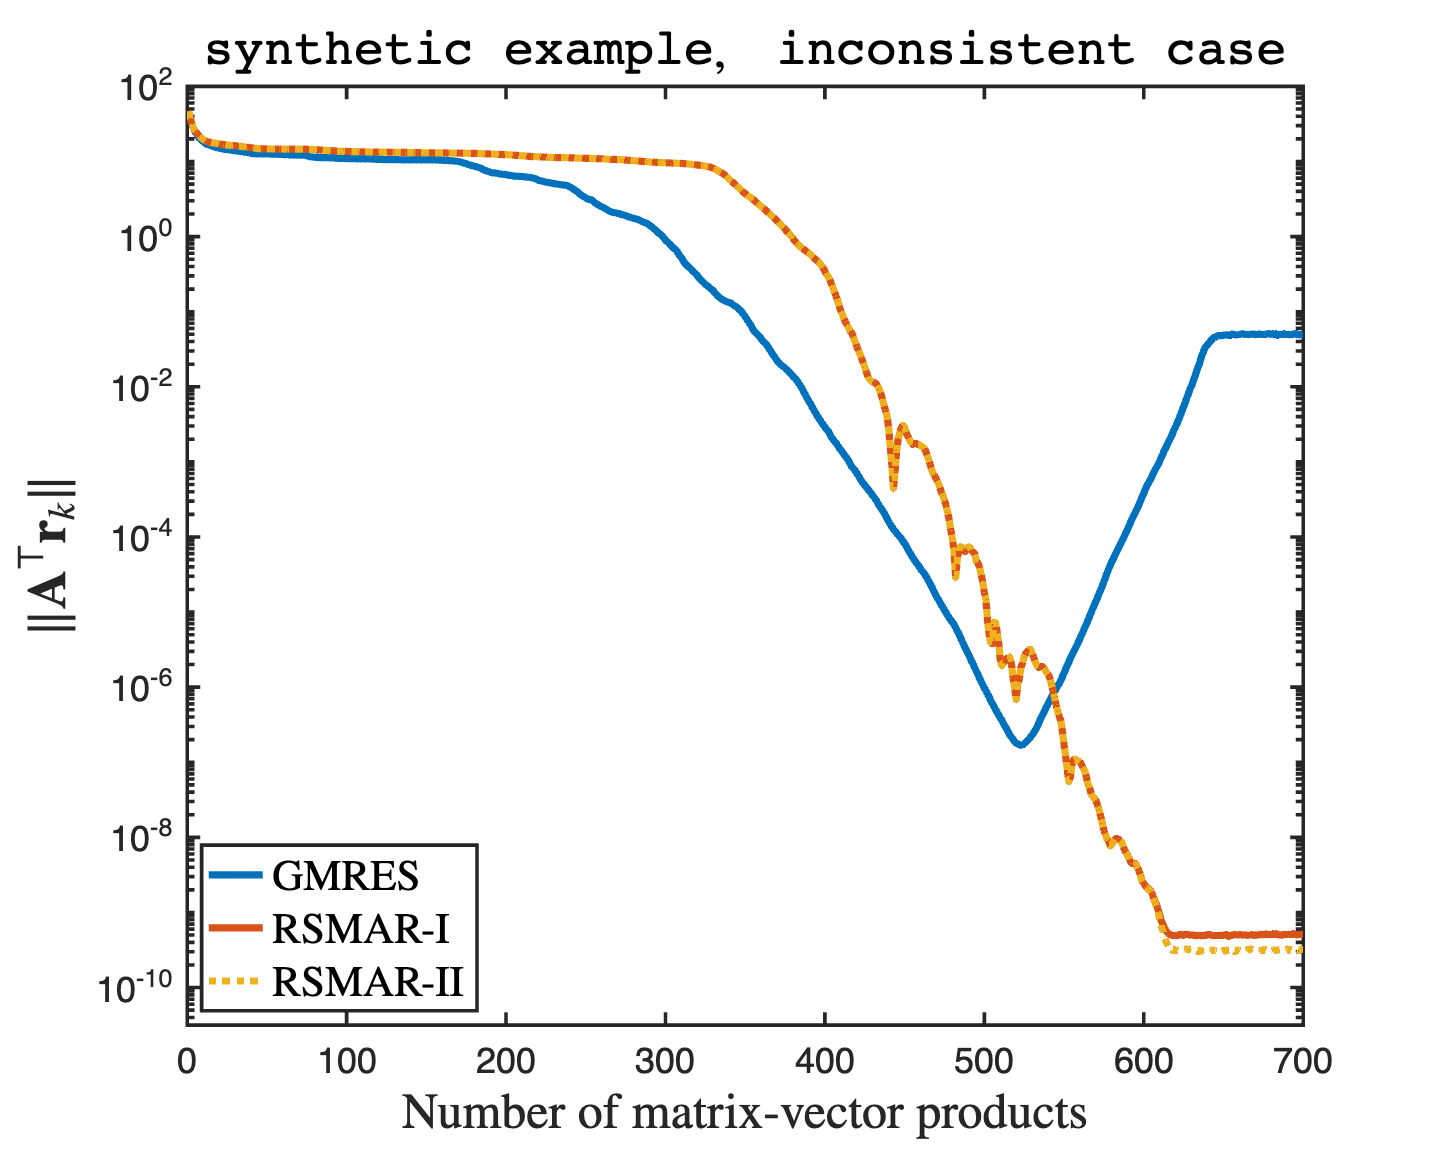

% range symmetric singular inconsistent system
b = randn(n,1);
tol = 1e-10; % maxit = 650;

[~, ~, mgs_gmres_resvec, mgs_gmres_Aresvec, mgs_gmres_Atresvec] = mgs_gmres(A, b, tol, maxit);
%[~, ~, hh_gmres_resvec, hh_gmres_Aresvec, hh_gmres_Atresvec] = mgs_gmres(A, b, tol, maxit);
[~, ~, rsmar1_resvec, rsmar1_Aresvec, rsmar1_Atresvec] = rsmar(A, b, tol, maxit, version=1);
[~, ~, rsmar2_resvec, rsmar2_Aresvec, rsmar2_Atresvec] = rsmar(A, b, tol, maxit, version=2);
% [~, ~,~, lsqr_Aresvec] = lsqr(A, b, tol, maxit);
% [~, ~,~, lsmr_Aresvec] = lsmr(A, b, tol, maxit);
% 
% set(0, 'defaultaxeslinewidth',  2);
% set(0, 'defaultaxesfontsize',   20);
% figure('Position',[180 120 800 640]); 
% semilogy(1:length(mgs_gmres_resvec), mgs_gmres_resvec, LineWidth=4);
% hold on;
% %semilogy(1:length(hh_gmres_resvec), hh_gmres_resvec, LineWidth=4, LineStyle=":");
% semilogy(1:length(rsmar1_resvec), rsmar1_resvec, LineWidth=4);
% semilogy(1:length(rsmar2_resvec), rsmar2_resvec, LineWidth=4, LineStyle=':');
% % semilogy(3:2:2*length(lsqr_Aresvec)+1, lsqr_Aresvec, LineWidth=4);
% % semilogy(3:2:2*length(lsmr_Aresvec)+1, lsmr_Aresvec, LineWidth=4,LineStyle=":");
% 
% hold off;
% 
% xlim([0, maxit]), ylim([44 mgs_gmres_resvec(1)+1])
% title('{\tt synthetic example},\quad{\tt inconsistent case}', Interpreter='latex',FontSize=28);
% xlabel('Number of matrix-vector products', Interpreter='latex', FontSize=28);
% ylabel('$\|\mathbf{r}_k\|$', Interpreter='latex', FontSize=30);
% legend({'GMRES', 'RSMAR-I', 'RSMAR-II'}, Interpreter='latex', FontSize=24, Location='best');
% 
% set(0, 'defaultaxeslinewidth',  2);
% set(0, 'defaultaxesfontsize',   20);
% figure('Position',[180 120 800 640]); 
% semilogy(1:length(mgs_gmres_Aresvec), mgs_gmres_Aresvec, LineWidth=4);
% hold on;
% % semilogy(1:length(hh_gmres_Aresvec), hh_gmres_Aresvec, LineWidth=4, LineStyle=":");
% semilogy(1:length(rsmar1_Aresvec), rsmar1_Aresvec, LineWidth=4);
% semilogy(1:length(rsmar2_Aresvec), rsmar2_Aresvec, LineWidth=4, LineStyle=':');
% % semilogy(3:2:2*length(lsqr_Aresvec)+1, lsqr_Aresvec, LineWidth=4);
% % semilogy(3:2:2*length(lsmr_Aresvec)+1, lsmr_Aresvec, LineWidth=4,LineStyle=":");
% 
% hold off;
% 
% xlim([0, maxit]), ylim([tol*10^(-0.5) 10^2])
% title('{\tt synthetic example},\quad{\tt inconsistent case}', Interpreter='latex',FontSize=28);
% xlabel('Number of matrix-vector products', Interpreter='latex', FontSize=28);
% ylabel('$\|\mathbf{Ar}_k\|$', Interpreter='latex', FontSize=30);
% legend({'GMRES', 'RSMAR-I', 'RSMAR-II'}, Interpreter='latex', FontSize=24, Location='SW');

set(0, 'defaultaxeslinewidth',  2);
set(0, 'defaultaxesfontsize',   20);
figure('Position',[180 120 800 640]); 
semilogy(1:length(mgs_gmres_Atresvec), mgs_gmres_Atresvec, LineWidth=4);
hold on;
% semilogy(1:length(hh_gmres_Atresvec), hh_gmres_Atresvec, LineWidth=4, LineStyle=":");
semilogy(1:length(rsmar1_Atresvec), rsmar1_Atresvec, LineWidth=4);
semilogy(1:length(rsmar2_Atresvec), rsmar2_Atresvec, LineWidth=4, LineStyle=':');
% semilogy(3:2:2*length(lsqr_Aresvec)+1, lsqr_Aresvec, LineWidth=4);
% semilogy(3:2:2*length(lsmr_Aresvec)+1, lsmr_Aresvec, LineWidth=4,LineStyle=":");

hold off;

xlim([0, maxit]), ylim([tol*10^(-0.5) 10^2])
title('{\tt synthetic example},\quad{\tt inconsistent case}', Interpreter='latex',FontSize=28);
xlabel('Number of matrix-vector products', Interpreter='latex', FontSize=28);
ylabel('$\|\mathbf{A}^\top\mathbf{r}_k\|$', Interpreter='latex', FontSize=30);
legend({'GMRES', 'RSMAR-I', 'RSMAR-II'}, Interpreter='latex', FontSize=24, Location='SW');
print('syn_incon','-depsc')

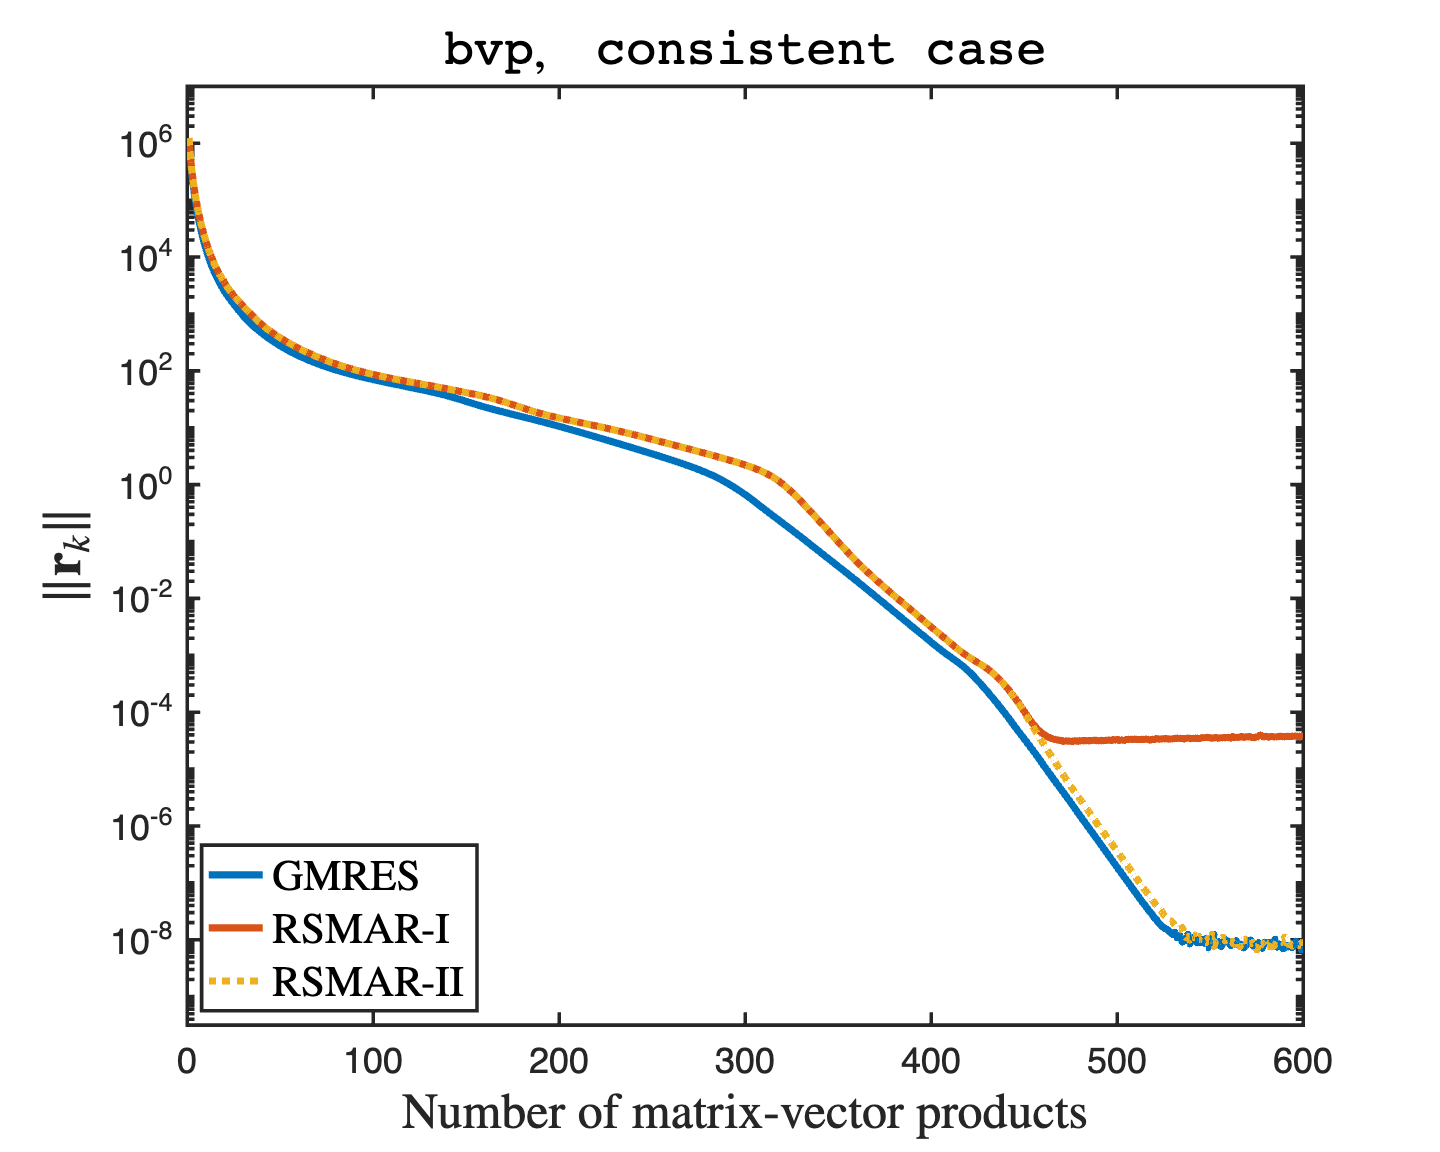

% range symmetric singular consistent system
clc; close all; clearvars;
m = 100; h = 1 / m; d = 10;
a1 = 1 + d * h / 2;
a2 = 1 - d * h / 2;
one = ones(m, 1);
T = spdiags([a2*one, -4*one, a1*one], [-1, 0, 1], m, m);
T(m, 1) = a1; T(1, m) = a2;
A = spdiags([one, one], [-1, 1], m, m);
A(1, m) = 1; A(m, 1) = 1;
A = kron(A, speye(m)) + kron(speye(m), T);
A = A/h/h;

rng("default"); b = A*randn(m*m,1);
tol = 1e-9; maxit = 600;

[~, ~, mgs_gmres_resvec, ~] = mgs_gmres(A, b, tol, maxit);
% [~, ~, hh_gmres_resvec, ~] = hh_gmres(A, b, tol, maxit);
[~, ~, rsmar1_resvec, ~] = rsmar(A, b, tol, maxit, version=1);
[~, ~, rsmar2_resvec, ~] = rsmar(A, b, tol, maxit, version=2);
% [~, ~, lsqr_resvec, ~] = lsqr(A, b, tol, maxit);
% [~, ~, lsmr_resvec, ~] = lsmr(A, b, tol, maxit);

set(0, 'defaultaxeslinewidth',  2);
set(0, 'defaultaxesfontsize',   20);
figure('Position',[180 120 800 640]);
semilogy(1:length(mgs_gmres_resvec), mgs_gmres_resvec, LineWidth=4);
hold on;
% semilogy(1:length(hh_gmres_resvec), hh_gmres_resvec, LineWidth=4, LineStyle=":");
semilogy(1:length(rsmar1_resvec), rsmar1_resvec, LineWidth=4);
semilogy(1:length(rsmar2_resvec), rsmar2_resvec, LineWidth=4, LineStyle=":");
% semilogy(3:2:2*length(lsqr_resvec)+1, lsqr_resvec, LineWidth=4);
% semilogy(3:2:2*length(lsmr_resvec)+1, lsmr_resvec, LineWidth=4,LineStyle=":");
hold off;
xlim([0, maxit]), ylim([tol*10^(-0.5) 10^7])
title('{\tt bvp},\quad{\tt consistent case}', Interpreter='latex',FontSize=28);
xlabel('Number of matrix-vector products', Interpreter='latex', FontSize=28);
ylabel('$\|\mathbf{r}_k\|$', Interpreter='latex', FontSize=30);
legend({'GMRES', 'RSMAR-I', 'RSMAR-II'}, Interpreter='latex', FontSize=24, Location='SW');
print('bvp_con','-depsc')

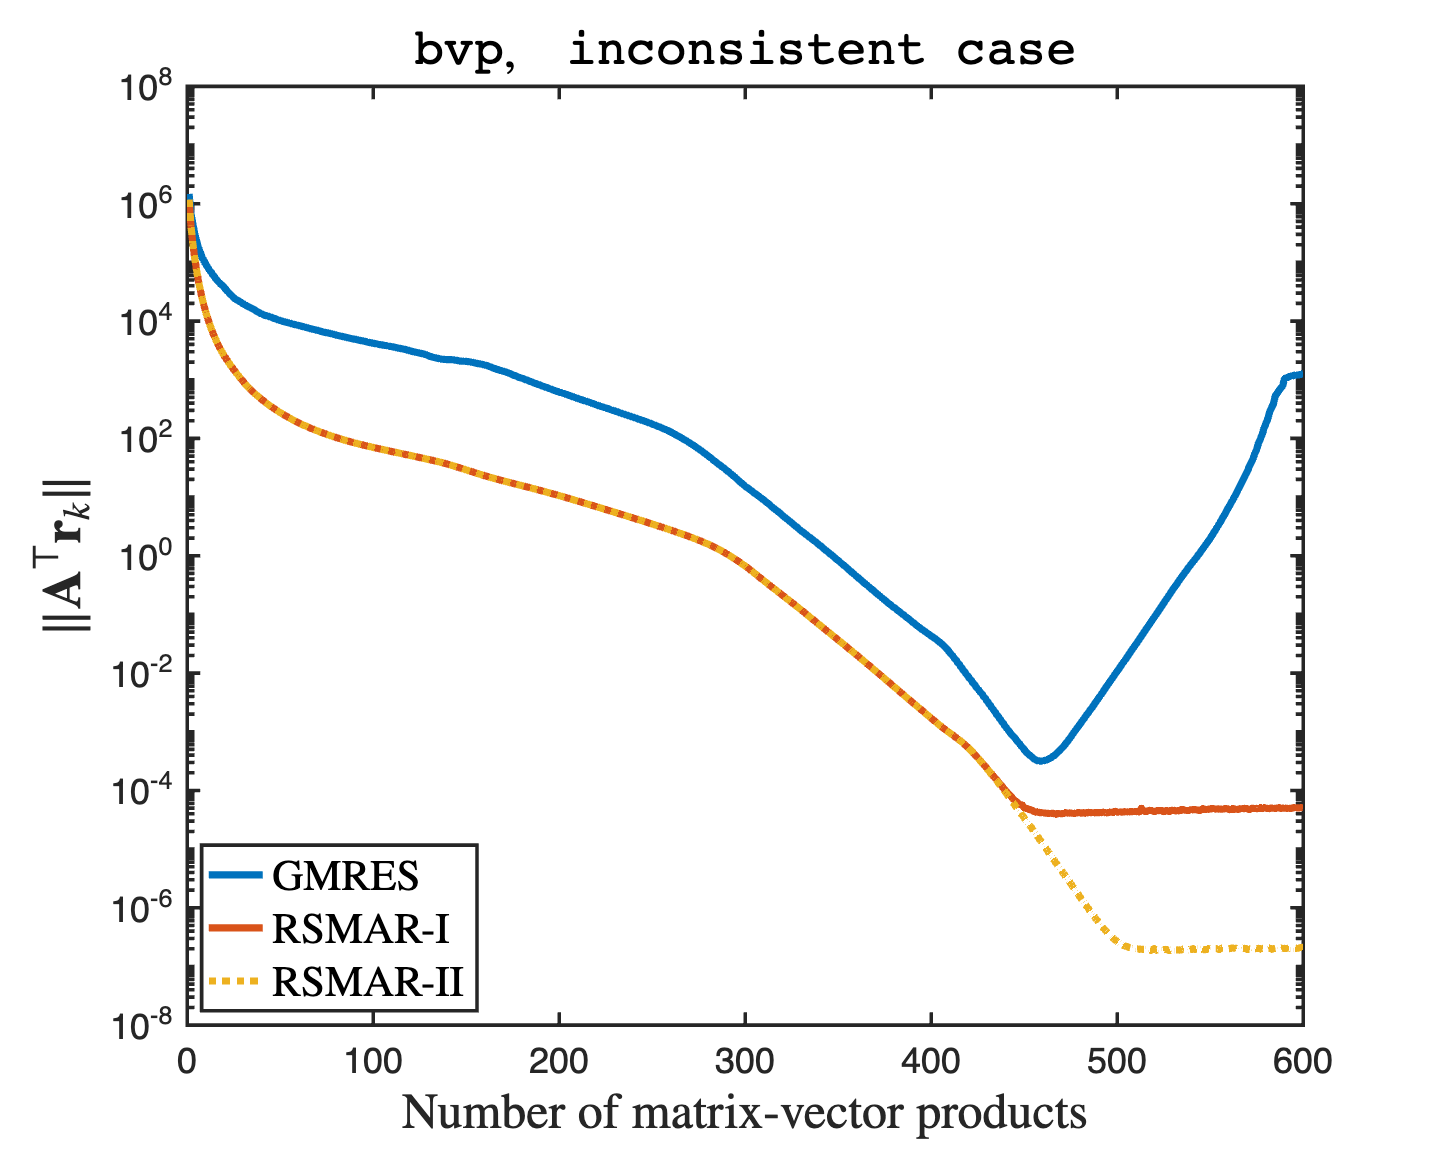

% range symmetric singular inconsistent system
rng("default");  b = randn(m*m,1);
tol = 1e-7; maxit = 600;
[~, ~, mgs_gmres_resvec, mgs_gmres_Aresvec, mgs_gmres_Atresvec] = mgs_gmres(A, b, tol, maxit);
% [~, ~, hh_gmres_resvec, hh_gmres_Aresvec, hh_gmres_Atresvec] = mgs_gmres(A, b, tol, maxit);
[~, ~, rsmar1_resvec, rsmar1_Aresvec, rsmar1_Atresvec] = rsmar(A, b, tol, maxit, version=1);
[~, ~, rsmar2_resvec, rsmar2_Aresvec, rsmar2_Atresvec] = rsmar(A, b, tol, maxit, version=2);
% [~, ~,~, lsqr_Aresvec] = lsqr(A, b, tol, maxit);
% [~, ~,~, lsmr_Aresvec] = lsmr(A, b, tol, maxit);

% set(0, 'defaultaxeslinewidth',  2);
% set(0, 'defaultaxesfontsize',   20);
% figure('Position',[180 120 800 640]); 
% semilogy(1:length(mgs_gmres_resvec), mgs_gmres_resvec, LineWidth=4);
% hold on;
% % semilogy(1:length(hh_gmres_resvec), hh_gmres_resvec, LineWidth=4, LineStyle=":");
% semilogy(1:length(rsmar1_resvec), rsmar1_resvec, LineWidth=4);
% semilogy(1:length(rsmar2_resvec), rsmar2_resvec, LineWidth=4, LineStyle=':');
% % semilogy(3:2:2*length(lsqr_Aresvec)+1, lsqr_Aresvec, LineWidth=4);
% % semilogy(3:2:2*length(lsmr_Aresvec)+1, lsmr_Aresvec, LineWidth=4,LineStyle=":");
% 
% hold off;
% 
% title('{\tt bvp},\quad{\tt inconsistent case}', Interpreter='latex',FontSize=28);
% xlabel('Number of matrix-vector products', Interpreter='latex', FontSize=28);
% ylabel('$\|\mathbf{r}_k\|$', Interpreter='latex', FontSize=30);
% legend({'GMRES', 'RSMAR-I', 'RSMAR-II'}, Interpreter='latex', FontSize=24, Location='best');
% % print('bvp_incon','-depsc')
% 
% set(0, 'defaultaxeslinewidth',  2);
% set(0, 'defaultaxesfontsize',   20);
% figure('Position',[180 120 800 640]); 
% semilogy(1:length(mgs_gmres_Aresvec), mgs_gmres_Aresvec, LineWidth=4);
% hold on;
% % semilogy(1:length(hh_gmres_Aresvec), hh_gmres_Aresvec, LineWidth=4, LineStyle=":");
% semilogy(1:length(rsmar1_Aresvec), rsmar1_Aresvec, LineWidth=4);
% semilogy(1:length(rsmar2_Aresvec), rsmar2_Aresvec, LineWidth=4, LineStyle=':');
% % semilogy(3:2:2*length(lsqr_Aresvec)+1, lsqr_Aresvec, LineWidth=4);
% % semilogy(3:2:2*length(lsmr_Aresvec)+1, lsmr_Aresvec, LineWidth=4,LineStyle=":");
% 
% hold off;
% 
% title('{\tt bvp},\quad{\tt inconsistent case}', Interpreter='latex',FontSize=28);
% xlabel('Number of matrix-vector products', Interpreter='latex', FontSize=28);
% ylabel('$\|\mathbf{Ar}_k\|$', Interpreter='latex', FontSize=30);
% legend({'GMRES', 'RSMAR-I', 'RSMAR-II'}, Interpreter='latex', FontSize=24, Location='SW');

set(0, 'defaultaxeslinewidth',  2);
set(0, 'defaultaxesfontsize',   20);
figure('Position',[180 120 800 640]); 
semilogy(1:length(mgs_gmres_Atresvec), mgs_gmres_Atresvec, LineWidth=4);
hold on;
% semilogy(1:length(hh_gmres_Atresvec), hh_gmres_Atresvec, LineWidth=4, LineStyle=":");
semilogy(1:length(rsmar1_Atresvec), rsmar1_Atresvec, LineWidth=4);
semilogy(1:length(rsmar2_Atresvec), rsmar2_Atresvec, LineWidth=4, LineStyle=':');
% semilogy(3:2:2*length(lsqr_Aresvec)+1, lsqr_Aresvec, LineWidth=4);
% semilogy(3:2:2*length(lsmr_Aresvec)+1, lsmr_Aresvec, LineWidth=4,LineStyle=":");

hold off;

title('{\tt bvp},\quad{\tt inconsistent case}', Interpreter='latex',FontSize=28);
xlabel('Number of matrix-vector products', Interpreter='latex', FontSize=28);
ylabel('$\|\mathbf{A}^\top\mathbf{r}_k\|$', Interpreter='latex', FontSize=30);
legend({'GMRES', 'RSMAR-I', 'RSMAR-II'}, Interpreter='latex', FontSize=24, Location='SW');
print('bvp_incon','-depsc')